clear
clc
close all

%% ============================================
%  LOAD MERGED DATA
%% ============================================
data  = readtable("C:\Users\arigi\Downloads\Totaldataset.csv");

names = data.Properties.VariableNames;

%% ============================================
%  COLUMN FINDER HELPER
%% ============================================
findCol = @(kw) find(contains(names, kw, 'IgnoreCase', true), 1);

%% ============================================
%  SPECIAL: BatteryTemp (exclude max column)
%% ============================================
btMatches      = find(contains(names, 'BatteryTemp', 'IgnoreCase', true));
btMatches      = btMatches(~contains(names(btMatches), 'max', 'IgnoreCase', true));
batteryTempCol = btMatches(1);

%% ============================================
%  SPECIAL: SOC (exclude displayed / min / max)
%% ============================================
socMatches = find(contains(names, 'SoC', 'IgnoreCase', true));
socMatches = socMatches( ...
    ~contains(names(socMatches), 'display', 'IgnoreCase', true) & ...
    ~contains(names(socMatches), 'min',     'IgnoreCase', true) & ...
    ~contains(names(socMatches), 'max',     'IgnoreCase', true));
socCol_idx = socMatches(1);

%% ============================================
%  AUTO-EXTRACT VARIABLES
%% ============================================
Velocity     = data{:, findCol('Velocity')};
Elevation    = data{:, findCol('Elevation')};
Throttle     = data{:, findCol('Throttle')};
Torque       = data{:, findCol('MotorTorque')};
Acceleration = data{:, findCol('LongitudinalAcceleration')};
Regen        = data{:, findCol('RegenerativeBraking')};
Voltage      = data{:, findCol('BatteryVoltage')};
Current      = data{:, findCol('BatteryCurrent')};
BatteryTemp  = data{:, batteryTempCol};
AmbientTemp  = data{:, findCol('AmbientTemp')};
AirCon       = data{:, findCol('AirCon')};
Heater       = data{:, findCol('HeaterCurrent')};
SOC          = data{:, socCol_idx};

%% ============================================
%  REMOVE MISSING VALUES
%% ============================================
idx = ~isnan(Velocity)    & ~isnan(Elevation)   & ~isnan(Throttle)  & ...
      ~isnan(Torque)      & ~isnan(Acceleration) & ~isnan(Regen)     & ...
      ~isnan(Voltage)     & ~isnan(Current)      & ~isnan(BatteryTemp) & ...
      ~isnan(AmbientTemp) & ~isnan(AirCon)       & ~isnan(Heater)    & ...
      ~isnan(SOC);

Velocity     = Velocity(idx);
Elevation    = Elevation(idx);
Throttle     = Throttle(idx);
Torque       = Torque(idx);
Acceleration = Acceleration(idx);
Regen        = Regen(idx);
Voltage      = Voltage(idx);
Current      = Current(idx);
BatteryTemp  = BatteryTemp(idx);
AmbientTemp  = AmbientTemp(idx);
AirCon       = AirCon(idx);
Heater       = Heater(idx);
SOC          = SOC(idx);

%% ============================================
%  FEATURE MATRIX
%% ============================================
X = [Velocity, Elevation, Throttle, Torque, Acceleration, Regen, ...
     Voltage, Current, BatteryTemp, AmbientTemp, AirCon, Heater];
y = SOC;

varNames = ["Velocity","Elevation","Throttle","Torque","Acceleration","Regen", ...
            "Voltage","Current","BatteryTemp","AmbientTemp","AirCon","Heater","SOC"];

%% ============================================
%  CORRELATION MATRIX
%% ============================================
corrMatrix = corrcoef([X y]);

disp("Correlation Matrix:")

Correlation Matrix:


disp(array2table(corrMatrix, 'VariableNames', cellstr(varNames), ...
                              'RowNames',      cellstr(varNames)))

                    Velocity    Elevation    Throttle      Torque      Acceleration     Regen       Voltage     Current     BatteryTemp    AmbientTemp     AirCon       Heater        SOC   
                    ________    _________    _________    _________    ____________    ________    _________    ________    ___________    ___________    _________    ________    _________

    Velocity               1     -0.98418     -0.27375     -0.13301      0.055114        0.9909     -0.98571     0.44501      -0.32469       -0.93905       0.2555

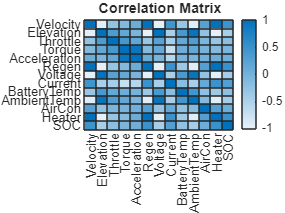


%% ============================================
%  HEATMAP
%% ============================================
figure
heatmap(cellstr(varNames), cellstr(varNames), corrMatrix, 'ColorLimits', [-1 1])
title("Correlation Matrix")


%% ============================================
%  FEATURE IMPORTANCE (SOC)
%% ============================================
features = varNames(1:12);
corr_SOC = corrMatrix(1:12, 13);
abs_corr = abs(corr_SOC);

influence = strings(12, 1);
for i = 1:12
    if     abs_corr(i) > 0.7;  influence(i) = "Very High";
    elseif abs_corr(i) > 0.4;  influence(i) = "High";
    elseif abs_corr(i) > 0.2;  influence(i) = "Medium";
    elseif abs_corr(i) > 0.1;  influence(i) = "Low";
    else;                       influence(i) = "Very Low";
    end
end

InfluenceTable = table(features', abs_corr, influence, ...
    'VariableNames', {'Feature', 'CorrelationWithSOC', 'Influence'});

disp(" ")

disp("Feature Influence on SOC:")

Feature Influence on SOC:


disp(InfluenceTable)

       Feature        CorrelationWithSOC    Influence 
    ______________    __________________    __________

    "Velocity"              0.46841         "High"    
    "Elevation"             0.46162         "High"    
    "Throttle"              0.21117         "Medium"  
    "Torque"               0.070295         "Very Low"
    "Acceleration"         0.028604         "Very Low"
    "Regen"                 0.48755         "High"    
    "Voltage"               0.45179         "High"    
    "Current"               0.27585         "Medium"  
    "BatteryTemp"           0.24967         "Medium"  
    "AmbientTemp"           0.43605         "High"    
    "AirCon"               0.046255         "Very Low"
    "Heater"                0.48752         "High"    

